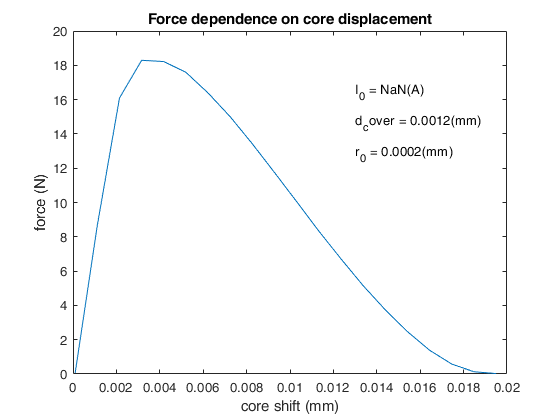

%  Puvodni_data = xlsread('Data.xlsx');
% M = Puvodni_data
% ----------------------------------------------------------
% shift(330)    I_0(55)     d_cover(5)      r_0(1)
%    20            6           11             5
% ----------------------------------------------------------
I_0 = 3;
d_cover = 7;
r_0 = 1;
% ----------------------------------------------------------
F = zeros(1,20); s = zeros(1,20);
for i = 1:20
    sila = (330 * (i-1)) + (55 * (I_0)) + (d_cover * 5) + r_0 + 1; 
    F(i) = M(sila,5);
    s(i) = M(sila,1);
end
% ----------------------------------------------------------
plot(s,F);
xlabel('core shift (mm)');
ylabel('force (N)');
title(['Force dependence on core displacement']);

text(0.013,max(F)-(max(F)/10),join(['I_0 = ' num2str(M(sila,2)) '(A)']))
text(0.013,max(F)-(2 * max(F)/10),join(['d_cover = ' num2str(M(sila,3)) '(mm)']))
text(0.013,max(F)-(3 * max(F)/10),join(['r_0 = ' num2str(M(sila,4)) '(mm)']))